I1=rgb2gray(imread('images\IMG_20181018_121003 (Klein).jpg'));
I2=rgb2gray(imread('images\IMG_20181018_121024 (Klein).jpg'));

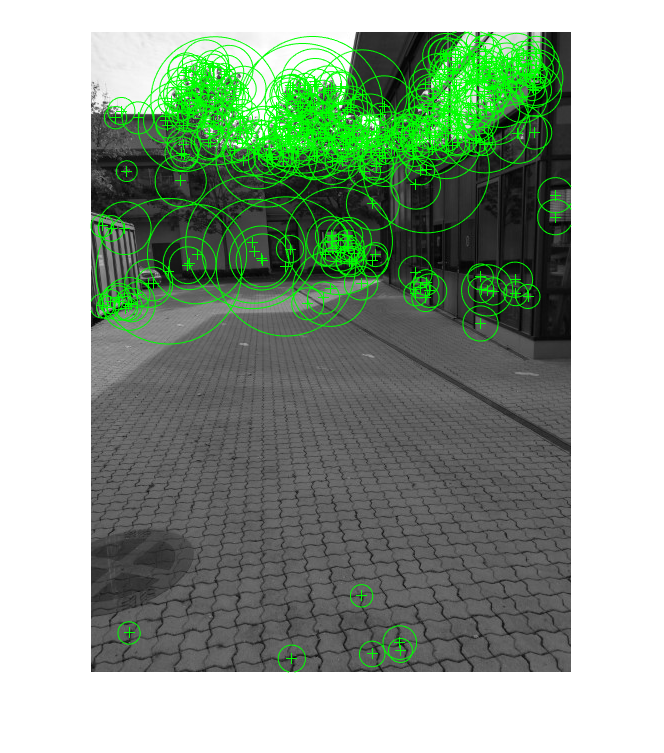

corners1=detectSURFFeatures(I1);
corners2=detectSURFFeatures(I2);
figure;imshow(I1);hold on
plot(corners1);

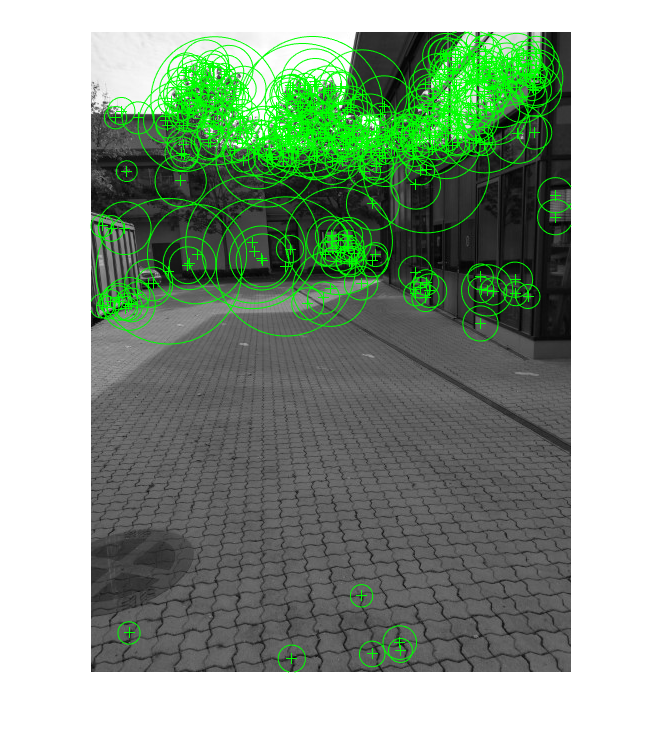

[features1,valid_corners1]=extractFeatures(I1,corners1);
[features2,valid_corners2]=extractFeatures(I2,corners2);
figure;imshow(I1);hold on
plot(valid_corners1);

indexPairs = matchFeatures(features1, features2, 'Unique', true)

indexPairs = 118×2 uint32 matrix
    1    1
    2    3
    4    2
    6   11
    8    4
    9    9
   12   13
   16   19
   18   18
   19   23


Take just the first y row of IndexPairs

matchedPoints1 = corners1(indexPairs(:,1), :);
matchedPoints2 = corners2(indexPairs(:,2), :);   

Perform RANSAC Automatically

transform = estimateGeometricTransform(matchedPoints1, matchedPoints2,...
        'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000)

transform =   projective2d with properties:

                 T: [3×3 single]
    Dimensionality: 2


Perform Brute Force Sample Consensus BFSAC

  c=matchedPoints1.Count

c = 118

 maxinliner=0;
 tform=transform;
   for p1=1:c
       for p2=p1+1:c
          for p3=p2+1:c
            for p4=p3+1:c
                
               if (maxinliner<11)
                   
                
                 selectedPoints1=[matchedPoints1(p1);matchedPoints1(p2);matchedPoints1(p3);matchedPoints1(p4)];
                  selectedPoints2=[matchedPoints2(p1);matchedPoints2(p2);matchedPoints2(p3);matchedPoints2(p4)];
                   
                vntform = fitgeotrans(selectedPoints2.Location,selectedPoints1.Location, 'projective');
                ntform=vntform.T;
                inliner=0;
                
                for n=1:c
                    matchedPoints1(n).Location;
                    diff=(ntform*[ matchedPoints1(n).Location,1]')-[ matchedPoints2(n).Location,1]';
                    diff=diff/diff(3);
                    diff=[diff(1);diff(2)];
                   idiff=norm(diff)
                   if(idiff<0.00)
                       inliner=inliner+1
                   end
                end
                
               if (inliner>maxinliner)
                   tform=ntform;
                   maxinliner=inliner;
               end
                end
                
            end
          end
       end
   end

idiff = single
0.0179

idiff = single
0.0183

idiff = single
0.0179

idiff = single
0.0197

idiff = single
0.0172

idiff = single
0.0191

idiff = single
0.0194

idiff = single
0.0192

idiff = single
0.0205

idiff = single
0.0190

idiff = single
0.0188

idiff = single
0.0267

idiff = single
0.0258

idiff = single
0.0172

idiff = single
0.0191

idiff = single
0.0234

idiff = single
0.0171

idiff = single
0.0172

idiff = single
0.0209

idiff = single
0.0197

idiff = single
0.0167

idiff = single
0.0249

idiff = single
0.0193

idiff = single
0.0286

idiff = single
0.0190

idiff = single
0.0181

idiff = single
0.0184

idiff = single
0.0190

idiff = single
0.0187

idiff = single
0.0177

idiff = single
0.0216

idiff = single
0.0186

idiff = single
0.0282

idiff = single
0.0174

idiff = single
0.0272

idiff = single
0.0191

idiff = single
0.0167

idiff = single
0.0223

idiff = single
0.0285

idiff = single
0.0232

idiff = single
0.0232

idiff = single
0.0166

idiff = single
0.0169

idiff = single
0.0202

idiff = single
0.0180

idiff = single
0.0172

idiff = single
0.0215

idiff = single
0.0177

idiff = single
0.0207

idiff = single
0.0171

idiff = single
0.0180

idiff = single
0.0177

idiff = single
0.0233

idiff = single
0.0197

idiff = single
0.0167

idiff = single
0.0201

idiff = single
0.0169

idiff = single
0.0169

idiff = single
0.0181

idiff = single
0.0191

idiff = single
0.0169

idiff = single
0.0171

idiff = single
0.0169

idiff = single
0.0179

idiff = single
0.0177

idiff = single
0.0205

idiff = single
0.0281

idiff = single
0.0184

idiff = single
0.0168

idiff = single
0.0181

idiff = single
0.0168

idiff = single
0.0192

idiff = single
0.0220

idiff = single
0.0177

idiff = single
0.0176

idiff = single
0.0172

idiff = single
0.0218

idiff = single
0.0171

idiff = single
0.0190

idiff = single
0.0175

idiff = single
0.0168

idiff = single
0.0467

idiff = single
0.0217

idiff = single
0.0173

idiff = single
0.0166

idiff = single
0.0171

idiff = single
0.0221

idiff = single
0.0184

idiff = single
0.0174

idiff = single
0.0251

idiff = single
0.0181

idiff = single
0.0175

idiff = single
0.0168

idiff = single
0.0177

idiff = single
0.0185

idiff = single
0.0183

idiff = single
0.0200

idiff = single
0.0186

idiff = single
0.0188

idiff = single
0.0349

idiff = single
0.0180

idiff = single
0.0180

idiff = single
0.0229

idiff = single
0.0166

idiff = single
0.0185

idiff = single
0.0169

idiff = single
0.0176

idiff = single
0.0168

idiff = single
0.0189

idiff = single
0.0166

idiff = single
0.0219

idiff = single
0.0184

idiff = single
0.0167

idiff = single
0.0176

idiff = single
0.0175

idiff = single
0.0175

idiff = single
0.0173

idiff = single
0.0237

idiff = single
0.0095

idiff = single
0.0097

idiff = single
0.0095

idiff = single
0.0106

idiff = single
0.0091

idiff = single
0.0102

idiff = single
0.0104

idiff = single
0.0102

idiff = single
0.0110

idiff = single
0.0098

idiff = single
0.0099

idiff = single
0.0133

idiff = single
0.0124

idiff = single
0.0092

idiff = single
0.0102

idiff = single
0.0116

idiff = single
0.0091

idiff = single
0.0092

idiff = single
0.0111

idiff = single
0.0102

idiff = single
0.0089

idiff = single
0.0121

idiff = single
0.0100

idiff = single
0.0139

idiff = single
0.0099

idiff = single
0.0096

idiff = single
0.0097

idiff = single
0.0099

idiff = single
0.0100

idiff = single
0.0095

idiff = single
0.0112

idiff = single
0.0100

idiff = single
0.0135

idiff = single
0.0090

idiff = single
0.0133

idiff = single
0.0100

idiff = single
0.0089

idiff = single
0.0116

idiff = single
0.0142

idiff = single
0.0118

idiff = single
0.0115

idiff = single
0.0090

idiff = single
0.0091

idiff = single
0.0108

idiff = single
0.0095

idiff = single
0.0092

idiff = single
0.0150

idiff = single
0.0099

idiff = single
0.0112

idiff = single
0.0094

idiff = single
0.0097

idiff = single
0.0099

idiff = single
0.0121

idiff = single
0.0107

idiff = single
0.0089

idiff = single
0.0109

idiff = single
0.0091

idiff = single
0.0091

idiff = single
0.0096

idiff = single
0.0103

idiff = single
0.0090

idiff = single
0.0091

idiff = single
0.0091

idiff = single
0.0105

idiff = single
0.0098

idiff = single
0.0137

idiff = single
0.0142

idiff = single
0.0099

idiff = single
0.0091

idiff = single
0.0097

idiff = single
0.0090

idiff = single
0.0101

idiff = single
0.0112

idiff = single
0.0095

idiff = single
0.0094

idiff = single
0.0091

idiff = single
0.0166

idiff = single
0.0091

idiff = single
0.0101

idiff = single
0.0093

idiff = single
0.0093

idiff = single
0.0220

idiff = single
0.0159

idiff = single
0.0093

idiff = single
0.0107

idiff = single
0.0092

idiff = single
0.0119

idiff = single
0.0098

idiff = single
0.0093

idiff = single
0.0125

idiff = single
0.0098

idiff = single
0.0094

idiff = single
0.0090

idiff = single
0.0096

idiff = single
0.0110

idiff = single
0.0098

idiff = single
0.0128

idiff = single
0.0110

idiff = single
0.0099

idiff = single
0.0170

idiff = single
0.0096

idiff = single
0.0097

idiff = single
0.0131

idiff = single
0.0109

idiff = single
0.0110

idiff = single
0.0091

idiff = single
0.0099

idiff = single
0.0092

idiff = single
0.0103

idiff = single
0.0107

idiff = single
0.0169

idiff = single
0.0099

idiff = single
0.0090

idiff = single
0.0095

idiff = single
0.0101

idiff = single
0.0102

idiff = single
0.0092

idiff = single
0.0130

idiff = single
0.0174

idiff = single
0.0177

idiff = single
0.0173

idiff = single
0.0189

idiff = single
0.0167

idiff = single
0.0183

idiff = single
0.0186

idiff = single
0.0185

idiff = single
0.0196

idiff = single
0.0184

idiff = single
0.0181

idiff = single
0.0252

idiff = single
0.0244

idiff = single
0.0167

idiff = single
0.0184

idiff = single
0.0222

idiff = single
0.0167

idiff = single
0.0167

idiff = single
0.0200

idiff = single
0.0189

idiff = single
0.0163

idiff = single
0.0235

idiff = single
0.0186

idiff = single
0.0269

idiff = single
0.0183

idiff = single
0.0175

idiff = single
0.0178

idiff = single
0.0183

idiff = single
0.0180

idiff = single
0.0172

idiff = single
0.0206

idiff = single
0.0179

idiff = single
0.0266

idiff = single
0.0170

idiff = single
0.0256

idiff = single
0.0184

idiff = single
0.0163

idiff = single
0.0212

idiff = single
0.0268

idiff = single
0.0221

idiff = single
0.0221

idiff = single
0.0162

idiff = single
0.0164

idiff = single
0.0193

idiff = single
0.0174

idiff = single
0.0167

idiff = single
0.0203

idiff = single
0.0171

idiff = single
0.0197

idiff = single
0.0166

idiff = single
0.0174

idiff = single
0.0171

idiff = single
0.0221

idiff = single
0.0188

idiff = single
0.0163

idiff = single
0.0192

idiff = single
0.0164

idiff = single
0.0164

idiff = single
0.0175

idiff = single
0.0183

idiff = single
0.0164

idiff = single
0.0166

idiff = single
0.0164

idiff = single
0.0173

idiff = single
0.0171

idiff = single
0.0195

idiff = single
0.0264

idiff = single
0.0178

idiff = single
0.0164

idiff = single
0.0175

idiff = single
0.0163

idiff = single
0.0184

idiff = single
0.0210

idiff = single
0.0171

idiff = single
0.0171

idiff = single
0.0167

idiff = single
0.0206

idiff = single
0.0167

idiff = single
0.0183

idiff = single
0.0170

idiff = single
0.0164

idiff = single
0.0436

idiff = single
0.0204

idiff = single
0.0168

idiff = single
0.0161

idiff = single
0.0166

idiff = single
0.0210

idiff = single
0.0177

idiff = single
0.0169

idiff = single
0.0237

idiff = single
0.0175

idiff = single
0.0169

idiff = single
0.0164

idiff = single
0.0171

idiff = single
0.0178

idiff = single
0.0176

idiff = single
0.0191

idiff = single
0.0179

idiff = single
0.0181

idiff = single
0.0326

idiff = single
0.0174

idiff = single
0.0174

idiff = single
0.0217

idiff = single
0.0161

idiff = single
0.0177

idiff = single
0.0165

idiff = single
0.0170

idiff = single
0.0164

idiff = single
0.0182

idiff = single
0.0161

idiff = single
0.0207

idiff = single
0.0178

idiff = single
0.0163

idiff = single
0.0171

idiff = single
0.0169

idiff = single
0.0169

idiff = single
0.0168

idiff = single
0.0224

idiff = single
0.0153

idiff = single
0.0156

idiff = single
0.0153

idiff = single
0.0167

idiff = single
0.0147

idiff = single
0.0162

idiff = single
0.0165

idiff = single
0.0164

idiff = single
0.0174

idiff = single
0.0162

idiff = single
0.0160

idiff = single
0.0227

idiff = single
0.0219

idiff = single
0.0147

idiff = single
0.0162

idiff = single
0.0198

idiff = single
0.0147

idiff = single
0.0147

idiff = single
0.0178

idiff = single
0.0167

idiff = single
0.0143

idiff = single
0.0211

idiff = single
0.0164

idiff = single
0.0243

idiff = single
0.0162

idiff = single
0.0154

idiff = single
0.0157

idiff = single
0.0161

idiff = single
0.0159

idiff = single
0.0151

idiff = single
0.0183

idiff = single
0.0158

idiff = single
0.0240

idiff = single
0.0150

idiff = single
0.0231

idiff = single
0.0163

idiff = single
0.0143

idiff = single
0.0189

idiff = single
0.0242

idiff = single
0.0197

idiff = single
0.0197

idiff = single
0.0142

idiff = single
0.0145

idiff = single
0.0171

idiff = single
0.0153

idiff = single
0.0147

idiff = single
0.0181

idiff = single
0.0151

idiff = single
0.0175

idiff = single
0.0146

idiff = single
0.0153

idiff = single
0.0150

idiff = single
0.0197

idiff = single
0.0167

idiff = single
0.0143

idiff = single
0.0170

idiff = single
0.0145

idiff = single
0.0145

idiff = single
0.0154

idiff = single
0.0162

idiff = single
0.0145

idiff = single
0.0146

idiff = single
0.0145

idiff = single
0.0152

idiff = single
0.0151

idiff = single
0.0173

idiff = single
0.0239

idiff = single
0.0157

idiff = single
0.0144

idiff = single
0.0154

idiff = single
0.0144

idiff = single
0.0163

idiff = single
0.0187

idiff = single
0.0151

idiff = single
0.0151

idiff = single
0.0147

idiff = single
0.0184

idiff = single
0.0147

idiff = single
0.0161

idiff = single
0.0150

idiff = single
0.0144

idiff = single
0.0403

idiff = single
0.0183

idiff = single
0.0148

idiff = single
0.0141

idiff = single
0.0146

idiff = single
0.0187

idiff = single
0.0156

idiff = single
0.0149

idiff = single
0.0212

idiff = single
0.0154

idiff = single
0.0149

idiff = single
0.0144

idiff = single
0.0151

idiff = single
0.0157

idiff = single
0.0156

idiff = single
0.0169

idiff = single
0.0158

idiff = single
0.0160

idiff = single
0.0298

idiff = single
0.0153

idiff = single
0.0153

idiff = single
0.0194

idiff = single
0.0141

idiff = single
0.0156

idiff = single
0.0145

idiff = single
0.0150

idiff = single
0.0144

idiff = single
0.0161

idiff = single
0.0141

idiff = single
0.0185

idiff = single
0.0157

idiff = single
0.0143

idiff = single
0.0150

idiff = single
0.0149

idiff = single
0.0148

idiff = single
0.0148

idiff = single
0.0201

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0089

idiff = single
0.0091

idiff = single
0.0088

idiff = single
0.0107

idiff = single
0.0106

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0099

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0090

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0103

idiff = single
0.0090

idiff = single
0.0113

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0089

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0093

idiff = single
0.0086

idiff = single
0.0113

idiff = single
0.0090

idiff = single
0.0109

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0094

idiff = single
0.0112

idiff = single
0.0097

idiff = single
0.0099

idiff = single
0.0086

idiff = single
0.0086

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0077

idiff = single
0.0083

idiff = single
0.0088

idiff = single
0.0083

idiff = single
0.0086

idiff = single
0.0083

idiff = single
0.0096

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0086

idiff = single
0.0086

idiff = single
0.0086

idiff = single
0.0080

idiff = single
0.0084

idiff = single
0.0076

idiff = single
0.0110

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0089

idiff = single
0.0095

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0075

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0083

idiff = single
0.0190

idiff = single
0.0075

idiff = single
0.0086

idiff = single
0.0075

idiff = single
0.0085

idiff = single
0.0091

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0102

idiff = single
0.0086

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0085

idiff = single
0.0080

idiff = single
0.0086

idiff = single
0.0078

idiff = single
0.0081

idiff = single
0.0088

idiff = single
0.0136

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0090

idiff = single
0.0074

idiff = single
0.0080

idiff = single
0.0087

idiff = single
0.0083

idiff = single
0.0084

idiff = single
0.0086

idiff = single
0.0075

idiff = single
0.0075

idiff = single
0.0086

idiff = single
0.0085

idiff = single
0.0086

idiff = single
0.0081

idiff = single
0.0080

idiff = single
0.0087

idiff = single
0.0093

idiff = single
0.2985

idiff = single
0.3135

idiff = single
0.2710

idiff = single
0.2589

idiff = single
0.3574

idiff = single
0.2604

idiff = single
0.2606

idiff = single
0.2772

idiff = single
0.2497

idiff = single
0.3421

idiff = single
0.3071

idiff = single
0.3094

idiff = single
0.3971

idiff = single
0.3008

idiff = single
0.2773

idiff = single
0.3876

idiff = single
0.2882

idiff = single
0.2881

idiff = single
0.2669

idiff = single
0.3458

idiff = single
0.3634

idiff = single
0.3850

idiff = single
0.3474

idiff = single
0.3175

idiff = single
0.3474

idiff = single
0.3068

idiff = single
0.3440

idiff = single
0.3532

idiff = single
0.2758

idiff = single
0.2831

idiff = single
0.3076

idiff = single
0.2613

idiff = single
0.3555

idiff = single
0.4356

idiff = single
0.3343

idiff = single
0.3320

idiff = single
0.3484

idiff = single
0.2878

idiff = single
0.2814

idiff = single
0.3142

idiff = single
0.3963

idiff = single
0.3926

idiff = single
0.3709

idiff = single
0.2613

idiff = single
0.3308

idiff = single
0.3474

idiff = single
0.1397

idiff = single
0.2036

idiff = single
0.2410

idiff = single
0.2048

idiff = single
0.2663

idiff = single
0.2007

idiff = single
0.2728

idiff = single
0.2438

idiff = single
0.3740

idiff = single
0.2456

idiff = single
0.3968

idiff = single
0.3474

idiff = single
0.2840

idiff = single
0.2489

idiff = single
0.3096

idiff = single
0.2823

idiff = single
0.3956

idiff = single
0.1801

idiff = single
0.2040

idiff = single
0.1480

idiff = single
0.2728

idiff = single
0.2676

idiff = single
0.3939

idiff = single
0.2881

idiff = single
0.3808

idiff = single
0.3067

idiff = single
0.3447

idiff = single
0.2639

idiff = single
0.3146

idiff = single
0.3296

idiff = single
0.1277

idiff = single
0.3187

idiff = single
0.2942

idiff = single
0.2829

idiff = single
0.2014

idiff = single
0.2832

idiff = single
0.1326

idiff = single
0.2722

idiff = single
0.1388

idiff = single
0.2595

idiff = single
0.2437

idiff = single
0.2757

idiff = single
0.2859

idiff = single
0.3189

idiff = single
0.2497

idiff = single
0.2607

idiff = single
0.3578

idiff = single
0.2484

idiff = single
0.1808

idiff = single
0.2699

idiff = single
0.1575

idiff = single
0.1798

idiff = single
0.3073

idiff = single
0.2762

idiff = single
0.2875

idiff = single
0.2512

idiff = single
0.1994

idiff = single
0.1368

idiff = single
0.1783

idiff = single
0.4016

idiff = single
0.1986

idiff = single
0.2157

idiff = single
0.2396

idiff = single
0.1384

idiff = single
0.1258

idiff = single
0.2529

idiff = single
0.2897

idiff = single
0.2539

idiff = single
0.1827

idiff = single
0.1784

idiff = single
0.3001

idiff = single
0.2236

idiff = single
0.0103

idiff = single
0.0105

idiff = single
0.0101

idiff = single
0.0101

idiff = single
0.0107

idiff = single
0.0101

idiff = single
0.0101

idiff = single
0.0102

idiff = single
0.0100

idiff = single
0.0106

idiff = single
0.0105

idiff = single
0.0109

idiff = single
0.0113

idiff = single
0.0103

idiff = single
0.0102

idiff = single
0.0111

idiff = single
0.0102

idiff = single
0.0102

idiff = single
0.0102

idiff = single
0.0107

idiff = single
0.0107

idiff = single
0.0112

idiff = single
0.0107

idiff = single
0.0111

idiff = single
0.0107

idiff = single
0.0104

idiff = single
0.0106

idiff = single
0.0107

idiff = single
0.0102

idiff = single
0.0102

idiff = single
0.0106

idiff = single
0.0101

idiff = single
0.0113

idiff = single
0.0109

idiff = single
0.0111

idiff = single
0.0106

idiff = single
0.0106

idiff = single
0.0105

idiff = single
0.0108

idiff = single
0.0107

idiff = single
0.0112

idiff = single
0.0109

idiff = single
0.0108

idiff = single
0.0102

idiff = single
0.0106

idiff = single
0.0106

idiff = single
0.0085

idiff = single
0.0094

idiff = single
0.0100

idiff = single
0.0093

idiff = single
0.0101

idiff = single
0.0093

idiff = single
0.0104

idiff = single
0.0100

idiff = single
0.0108

idiff = single
0.0100

idiff = single
0.0109

idiff = single
0.0107

idiff = single
0.0102

idiff = single
0.0100

idiff = single
0.0104

idiff = single
0.0102

idiff = single
0.0109

idiff = single
0.0090

idiff = single
0.0093

idiff = single
0.0086

idiff = single
0.0107

idiff = single
0.0101

idiff = single
0.0109

idiff = single
0.0103

idiff = single
0.0108

idiff = single
0.0105

idiff = single
0.0108

idiff = single
0.0101

idiff = single
0.0105

idiff = single
0.0105

idiff = single
0.0085

idiff = single
0.0105

idiff = single
0.0104

idiff = single
0.0102

idiff = single
0.0093

idiff = single
0.0127

idiff = single
0.0085

idiff = single
0.0101

idiff = single
0.0080

idiff = single
0.0100

idiff = single
0.0101

idiff = single
0.0102

idiff = single
0.0102

idiff = single
0.0109

idiff = single
0.0099

idiff = single
0.0100

idiff = single
0.0107

idiff = single
0.0099

idiff = single
0.0091

idiff = single
0.0102

idiff = single
0.0087

idiff = single
0.0090

idiff = single
0.0105

idiff = single
0.0113

idiff = single
0.0103

idiff = single
0.0099

idiff = single
0.0096

idiff = single
0.0080

idiff = single
0.0090

idiff = single
0.0109

idiff = single
0.0093

idiff = single
0.0095

idiff = single
0.0099

idiff = single
0.0080

idiff = single
0.0084

idiff = single
0.0100

idiff = single
0.0103

idiff = single
0.0100

idiff = single
0.0090

idiff = single
0.0089

idiff = single
0.0103

idiff = single
0.0100

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0048

idiff = single
0.0046

idiff = single
0.0051

idiff = single
0.0047

idiff = single
0.0046

idiff = single
0.0047

idiff = single
0.0045

idiff = single
0.0049

idiff = single
0.0048

idiff = single
0.0041

idiff = single
0.0042

idiff = single
0.0050

idiff = single
0.0047

idiff = single
0.0044

idiff = single
0.0050

idiff = single
0.0050

idiff = single
0.0045

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0043

idiff = single
0.0048

idiff = single
0.0039

inliner = 1

idiff = single
0.0048

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0048

idiff = single
0.0047

idiff = single
0.0049

idiff = single
0.0045

idiff = single
0.0047

idiff = single
0.0040

inliner = 2

idiff = single
0.0052

idiff = single
0.0040

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0044

idiff = single
0.0040

inliner = 3

idiff = single
0.0044

idiff = single
0.0045

idiff = single
0.0051

idiff = single
0.0051

idiff = single
0.0046

idiff = single
0.0049

idiff = single
0.0050

idiff = single
0.0059

idiff = single
0.0048

idiff = single
0.0045

idiff = single
0.0049

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0043

idiff = single
0.0046

idiff = single
0.0051

idiff = single
0.0046

idiff = single
0.0051

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0047

idiff = single
0.0050

idiff = single
0.0050

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0054

idiff = single
0.0040

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0047

idiff = single
0.0045

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0050

idiff = single
0.0067

idiff = single
0.0050

idiff = single
0.0047

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0042

idiff = single
0.0063

idiff = single
0.0049

idiff = single
0.0053

idiff = single
0.0049

idiff = single
0.0044

idiff = single
0.0048

idiff = single
0.0049

idiff = single
0.0042

idiff = single
0.0048

idiff = single
0.0049

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0039

inliner = 4

idiff = single
0.0049

idiff = single
0.0048

idiff = single
0.0046

idiff = single
0.0054

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0048

idiff = single
0.0049

idiff = single
0.0047

idiff = single
0.0053

idiff = single
0.0069

idiff = single
0.0048

idiff = single
0.0050

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0049

idiff = single
0.0050

idiff = single
0.0044

idiff = single
0.0089

idiff = single
0.0090

idiff = single
0.0089

idiff = single
0.0093

idiff = single
0.0088

idiff = single
0.0091

idiff = single
0.0092

idiff = single
0.0092

idiff = single
0.0095

idiff = single
0.0094

idiff = single
0.0091

idiff = single
0.0122

idiff = single
0.0119

idiff = single
0.0088

idiff = single
0.0092

idiff = single
0.0109

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0097

idiff = single
0.0095

idiff = single
0.0087

idiff = single
0.0115

idiff = single
0.0094

idiff = single
0.0131

idiff = single
0.0093

idiff = single
0.0090

idiff = single
0.0091

idiff = single
0.0093

idiff = single
0.0090

idiff = single
0.0088

idiff = single
0.0101

idiff = single
0.0090

idiff = single
0.0130

idiff = single
0.0091

idiff = single
0.0125

idiff = single
0.0093

idiff = single
0.0087

idiff = single
0.0103

idiff = single
0.0130

idiff = single
0.0108

idiff = single
0.0108

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0094

idiff = single
0.0089

idiff = single
0.0088

idiff = single
0.0090

idiff = single
0.0086

idiff = single
0.0095

idiff = single
0.0085

idiff = single
0.0089

idiff = single
0.0085

idiff = single
0.0107

idiff = single
0.0092

idiff = single
0.0087

idiff = single
0.0094

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0089

idiff = single
0.0091

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0084

idiff = single
0.0086

idiff = single
0.0087

idiff = single
0.0128

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0089

idiff = single
0.0087

idiff = single
0.0093

idiff = single
0.0103

idiff = single
0.0088

idiff = single
0.0089

idiff = single
0.0088

idiff = single
0.0090

idiff = single
0.0088

idiff = single
0.0092

idiff = single
0.0088

idiff = single
0.0085

idiff = single
0.0230

idiff = single
0.0090

idiff = single
0.0087

idiff = single
0.0078

idiff = single
0.0086

idiff = single
0.0100

idiff = single
0.0090

idiff = single
0.0088

idiff = single
0.0115

idiff = single
0.0088

idiff = single
0.0087

idiff = single
0.0087

idiff = single
0.0088

idiff = single
0.0085

idiff = single
0.0089

idiff = single
0.0087

idiff = single
0.0086

idiff = single
0.0092

idiff = single
0.0163

idiff = single
0.0089

idiff = single
0.0088

idiff = single
0.0102

idiff = single
0.0077

idiff = single
0.0084

idiff = single
0.0087

idiff = single
0.0085

idiff = single
0.0085

idiff = single
0.0090

idiff = single
0.0078

idiff = single
0.0090

idiff = single
0.0089

idiff = single
0.0086

idiff = single
0.0088

idiff = single
0.0084

idiff = single
0.0083

idiff = single
0.0088

idiff = single
0.0106

idiff = single
0.0064

idiff = single
0.0064

idiff = single
0.0063

idiff = single
0.0059

idiff = single
0.0067

idiff = single
0.0060

idiff = single
0.0060

idiff = single
0.0061

idiff = single
0.0058

idiff = single
0.0066

idiff = single
0.0063

idiff = single
0.0062

idiff = single
0.0066

idiff = single
0.0066

idiff = single
0.0061

idiff = single
0.0064

idiff = single
0.0065

idiff = single
0.0065

idiff = single
0.0059

idiff = single
0.0064

idiff = single
0.0067

idiff = single
0.0065

idiff = single
0.0065

idiff = single
0.0064

idiff = single
0.0065

idiff = single
0.0064

idiff = single
0.0065

idiff = single
0.0065

idiff = single
0.0062

idiff = single
0.0064

idiff = single
0.0061

idiff = single
0.0061

idiff = single
0.0066

idiff = single
0.0070

idiff = single
0.0064

idiff = single
0.0064

idiff = single
0.0067

idiff = single
0.0059

idiff = single
0.0062

idiff = single
0.0062

idiff = single
0.0065

idiff = single
0.0067

idiff = single
0.0067

idiff = single
0.0059

idiff = single
0.0065

idiff = single
0.0066

idiff = single
0.0034

inliner = 1

idiff = single
0.0058

idiff = single
0.0057

idiff = single
0.0061

idiff = single
0.0063

idiff = single
0.0058

idiff = single
0.0058

idiff = single
0.0058

idiff = single
0.0068

idiff = single
0.0058

idiff = single
0.0067

idiff = single
0.0066

idiff = single
0.0063

idiff = single
0.0059

idiff = single
0.0066

idiff = single
0.0065

idiff = single
0.0067

idiff = single
0.0054

idiff = single
0.0059

idiff = single
0.0038

inliner = 2

idiff = single
0.0061

idiff = single
0.0062

idiff = single
0.0067

idiff = single
0.0063

idiff = single
0.0067

idiff = single
0.0063

idiff = single
0.0063

idiff = single
0.0063

idiff = single
0.0065

idiff = single
0.0066

idiff = single
0.0027

inliner = 3

idiff = single
0.0066

idiff = single
0.0062

idiff = single
0.0065

idiff = single
0.0061

idiff = single
0.0104

idiff = single
0.0030

inliner = 4

idiff = single
0.0064

idiff = single
0.0051

idiff = single
0.0064

idiff = single
0.0056

idiff = single
0.0062

idiff = single
0.0065

idiff = single
0.0062

idiff = single
0.0061

idiff = single
0.0064

idiff = single
0.0067

idiff = single
0.0062

idiff = single
0.0052

idiff = single
0.0062

idiff = single
0.0043

idiff = single
0.0053

idiff = single
0.0063

idiff = single
0.0072

idiff = single
0.0064

idiff = single
0.0062

idiff = single
0.0049

idiff = single
0.0050

idiff = single
0.0051

idiff = single
0.0067

idiff = single
0.0058

idiff = single
0.0062

idiff = single
0.0059

idiff = single
0.0051

idiff = single
0.0026

inliner = 5

idiff = single
0.0061

idiff = single
0.0065

idiff = single
0.0063

idiff = single
0.0057

idiff = single
0.0056

idiff = single
0.0065

idiff = single
0.0052

idiff = single
0.0158

idiff = single
0.0162

idiff = single
0.0160

idiff = single
0.0184

idiff = single
0.0147

idiff = single
0.0176

idiff = single
0.0180

idiff = single
0.0176

idiff = single
0.0194

idiff = single
0.0165

idiff = single
0.0168

idiff = single
0.0244

idiff = single
0.0224

idiff = single
0.0150

idiff = single
0.0174

idiff = single
0.0205

idiff = single
0.0150

idiff = single
0.0150

idiff = single
0.0196

idiff = single
0.0173

idiff = single
0.0143

idiff = single
0.0217

idiff = single
0.0169

idiff = single
0.0259

idiff = single
0.0166

idiff = single
0.0160

idiff = single
0.0161

idiff = single
0.0166

idiff = single
0.0170

idiff = single
0.0158

idiff = single
0.0196

idiff = single
0.0171

idiff = single
0.0249

idiff = single
0.0144

idiff = single
0.0244

idiff = single
0.0169

idiff = single
0.0143

idiff = single
0.0205

idiff = single
0.0266

idiff = single
0.0210

idiff = single
0.0203

idiff = single
0.0144

idiff = single
0.0146

idiff = single
0.0189

idiff = single
0.0158

idiff = single
0.0149

idiff = single
0.0274

idiff = single
0.0170

idiff = single
0.0198

idiff = single
0.0159

idiff = single
0.0162

idiff = single
0.0170

idiff = single
0.0218

idiff = single
0.0187

idiff = single
0.0142

idiff = single
0.0190

idiff = single
0.0145

idiff = single
0.0146

idiff = single
0.0162

idiff = single
0.0178

idiff = single
0.0146

idiff = single
0.0150

idiff = single
0.0146

idiff = single
0.0183

idiff = single
0.0168

idiff = single
0.0248

idiff = single
0.0265

idiff = single
0.0168

idiff = single
0.0145

idiff = single
0.0162

idiff = single
0.0144

idiff = single
0.0172

idiff = single
0.0196

idiff = single
0.0158

idiff = single
0.0154

idiff = single
0.0149

idiff = single
0.0303

idiff = single
0.0149

idiff = single
0.0171

idiff = single
0.0155

idiff = single
0.0156

idiff = single
0.0448

idiff = single
0.0290

idiff = single
0.0153

idiff = single
0.0185

idiff = single
0.0153

idiff = single
0.0213

idiff = single
0.0166

idiff = single
0.0153

idiff = single
0.0227

idiff = single
0.0166

idiff = single
0.0156

idiff = single
0.0144

idiff = single
0.0161

idiff = single
0.0193

idiff = single
0.0166

idiff = single
0.0230

idiff = single
0.0192

idiff = single
0.0168

idiff = single
0.0330

idiff = single
0.0160

idiff = single
0.0164

idiff = single
0.0239

idiff = single
0.0188

idiff = single
0.0193

idiff = single
0.0146

idiff = single
0.0170

idiff = single
0.0154

idiff = single
0.0178

idiff = single
0.0186

idiff = single
0.0309

idiff = single
0.0169

idiff = single
0.0147

idiff = single
0.0159

idiff = single
0.0173

idiff = single
0.0176

idiff = single
0.0151

idiff = single
0.0238

idiff = single
0.0061

idiff = single
0.0062

idiff = single
0.0061

idiff = single
0.0058

idiff = single
0.0064

idiff = single
0.0058

idiff = single
0.0058

idiff = single
0.0059

idiff = single
0.0058

idiff = single
0.0064

idiff = single
0.0061

idiff = single
0.0068

idiff = single
0.0070

idiff = single
0.0062

idiff = single
0.0059

idiff = single
0.0066

idiff = single
0.0062

idiff = single
0.0062

idiff = single
0.0059

idiff = single
0.0062

idiff = single
0.0063

idiff = single
0.0068

idiff = single
0.0063

idiff = single
0.0073

idiff = single
0.0063

idiff = single
0.0061

idiff = single
0.0063

idiff = single
0.0063

idiff = single
0.0060

idiff = single
0.0061

idiff = single
0.0061

idiff = single
0.0059

idiff = single
0.0074

idiff = single
0.0067

idiff = single
0.0070

idiff = single
0.0062

idiff = single
0.0063

idiff = single
0.0061

idiff = single
0.0071

idiff = single
0.0064

idiff = single
0.0066

idiff = single
0.0063

idiff = single
0.0063

idiff = single
0.0058

idiff = single
0.0062

idiff = single
0.0063

idiff = single
0.0039

inliner = 1

idiff = single
0.0056

idiff = single
0.0057

idiff = single
0.0058

idiff = single
0.0060

idiff = single
0.0056

idiff = single
0.0061

idiff = single
0.0057

idiff = single
0.0064

idiff = single
0.0057

idiff = single
0.0063

idiff = single
0.0063

idiff = single
0.0061

idiff = single
0.0058

idiff = single
0.0062

idiff = single
0.0062

idiff = single
0.0063

idiff = single
0.0052

idiff = single
0.0057

idiff = single
0.0040

idiff = single
0.0070

idiff = single
0.0060

idiff = single
0.0063

idiff = single
0.0061

idiff = single
0.0063

idiff = single
0.0061

idiff = single
0.0063

idiff = single
0.0060

idiff = single
0.0062

idiff = single
0.0063

idiff = single
0.0035

inliner = 2

idiff = single
0.0062

idiff = single
0.0060

idiff = single
0.0061

idiff = single
0.0058

idiff = single
0.0132

idiff = single
0.0037

inliner = 3

idiff = single
0.0061

idiff = single
0.0049

idiff = single
0.0061

idiff = single
0.0057

idiff = single
0.0060

idiff = single
0.0061

idiff = single
0.0066

idiff = single
0.0059

idiff = single
0.0060

idiff = single
0.0063

idiff = single
0.0059

idiff = single
0.0050

idiff = single
0.0059

idiff = single
0.0044

idiff = single
0.0051

idiff = single
0.0061

idiff = single
0.0089

idiff = single
0.0061

idiff = single
0.0059

idiff = single
0.0053

idiff = single
0.0047

idiff = single
0.0050

idiff = single
0.0063

idiff = single
0.0056

idiff = single
0.0059

idiff = single
0.0057

idiff = single
0.0049

idiff = single
0.0035

inliner = 4

idiff = single
0.0059

idiff = single
0.0061

idiff = single
0.0060

idiff = single
0.0054

idiff = single
0.0053

idiff = single
0.0062

idiff = single
0.0057

idiff = single
0.0053

idiff = single
0.0052

idiff = single
0.0052

idiff = single
0.0046

idiff = single
0.0056

idiff = single
0.0047

idiff = single
0.0046

idiff = single
0.0048

idiff = single
0.0043

idiff = single
0.0053

idiff = single
0.0051

idiff = single
0.0042

idiff = single
0.0047

idiff = single
0.0054

idiff = single
0.0048

idiff = single
0.0048

idiff = single
0.0054

idiff = single
0.0054

idiff = single
0.0044

idiff = single
0.0051

idiff = single
0.0057

idiff = single
0.0047

idiff = single
0.0052

idiff = single
0.0042

idiff = single
0.0053

idiff = single
0.0052

idiff = single
0.0053

idiff = single
0.0053

idiff = single
0.0049

idiff = single
0.0052

idiff = single
0.0046

idiff = single
0.0049

idiff = single
0.0045

idiff = single
0.0059

idiff = single
0.0043

idiff = single
0.0052

idiff = single
0.0056

idiff = single
0.0044

idiff = single
0.0039

inliner = 1

idiff = single
0.0045

idiff = single
0.0049

idiff = single
0.0056

idiff = single
0.0056

idiff = single
0.0045

idiff = single
0.0053

idiff = single
0.0055

idiff = single
0.0014

inliner = 2

idiff = single
0.0046

idiff = single
0.0042

idiff = single
0.0049

idiff = single
0.0051

idiff = single
0.0046

idiff = single
0.0041

idiff = single
0.0044

idiff = single
0.0057

idiff = single
0.0044

idiff = single
0.0056

idiff = single
0.0056

idiff = single
0.0051

idiff = single
0.0046

idiff = single
0.0055

idiff = single
0.0054

idiff = single
0.0056

idiff = single
0.0042

idiff = single
0.0047

idiff = single
0.0020

inliner = 3

idiff = single
0.0038

inliner = 4

idiff = single
0.0050

idiff = single
0.0056

idiff = single
0.0051

idiff = single
0.0056

idiff = single
0.0050

idiff = single
0.0048

idiff = single
0.0051

idiff = single
0.0054

idiff = single
0.0055

idiff = single
3.5279e-04

inliner = 5

idiff = single
0.0055

idiff = single
0.0050

idiff = single
0.0053

idiff = single
0.0050

idiff = single
0.0070

idiff = single
7.8498e-04

inliner = 6

idiff = single
0.0053

idiff = single
0.0041

idiff = single
0.0052

idiff = single
0.0039

inliner = 7

idiff = single
0.0050

idiff = single
0.0053

idiff = single
0.0043

idiff = single
0.0049

idiff = single
0.0052

idiff = single
0.0056

idiff = single
0.0050

idiff = single
0.0038

inliner = 8

idiff = single
0.0050

idiff = single
0.0027

inliner = 9

idiff = single
0.0040

inliner = 10

idiff = single
0.0051

idiff = single
0.0044

idiff = single
0.0052

idiff = single
0.0050

idiff = single
0.0031

inliner = 11

idiff = single
0.0039

inliner = 12

idiff = single
0.0038

inliner = 13

idiff = single
0.0056

idiff = single
0.0046

idiff = single
0.0051

idiff = single
0.0046

idiff = single
0.0040

idiff = single
2.1425e-04

inliner = 14

idiff = single
0.0049

idiff = single
0.0054

idiff = single
0.0051

idiff = single
0.0045

idiff = single
0.0044

idiff = single
0.0054

idiff = single
0.0033

inliner = 15

height=480*2

height = 960

width=640

width = 640

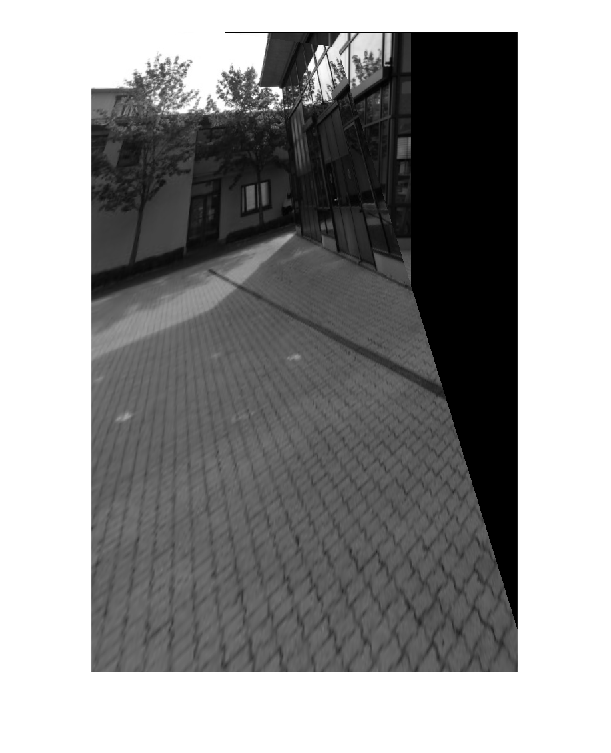

   % Initialize the "empty" panorama.
panorama = zeros([height width 1], 'like', I1);

%% Step 4 - Create the Panorama
% Use |imwarp| to map images into the panorama and use
% |vision.AlphaBlender| to overlay the images together.

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [0 width];
yLimits = [0 height];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama.
   
    % Transform I into the panorama.
    warpedImage = imwarp(I1,projective2d(eye(3,3)), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I1,1),size(I1,2)), projective2d(eye(3,3)), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);

    
     % Transform I into the panorama.
    warpedImage = imwarp(I2, projective2d(tform), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I2,1),size(I2,2)), projective2d(tform), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);

    

figure
imshow(panorama)